clear, clc

## LOAD FINAL PARAMETERS (DIFFERENT TRIALS)

MVC = '60';
trials = 5;
for ii = 1:trials
    trial{1,ii} = num2str(ii);
end
ErrFnc = 'moo';
OptAlg = 'godlike';
model = 'bestparameters_new';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters';

for i = 1:trials
    name = [MVC '_' trial{i} '_' OptAlg '_' ErrFnc '_' model];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## LOAD FINAL PARAMETERS (MULTIPLE COPIES)

MVC = '10';
Trial = '2';
trials = 10;
for ii = 1:trials
    trial{1,ii} = num2str(ii);
end
ErrFnc = 'moo';
OptAlg = 'godlike';
model = 'bestparameters_new';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters\Copies';

for i = 1:trials
    name = [MVC '_' Trial '_' OptAlg '_' ErrFnc '_' model '_' trial{i}];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

% Load CoV values
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Trial Information';
names2 = [MVC '_MVC_no_BISI'];
data2 = load([path '\' names2 '.mat']);
clear path, clear names2, clear i, clear MVC

## PLOT THE COMPARISON IN PARAMETER DISTRIBUTION

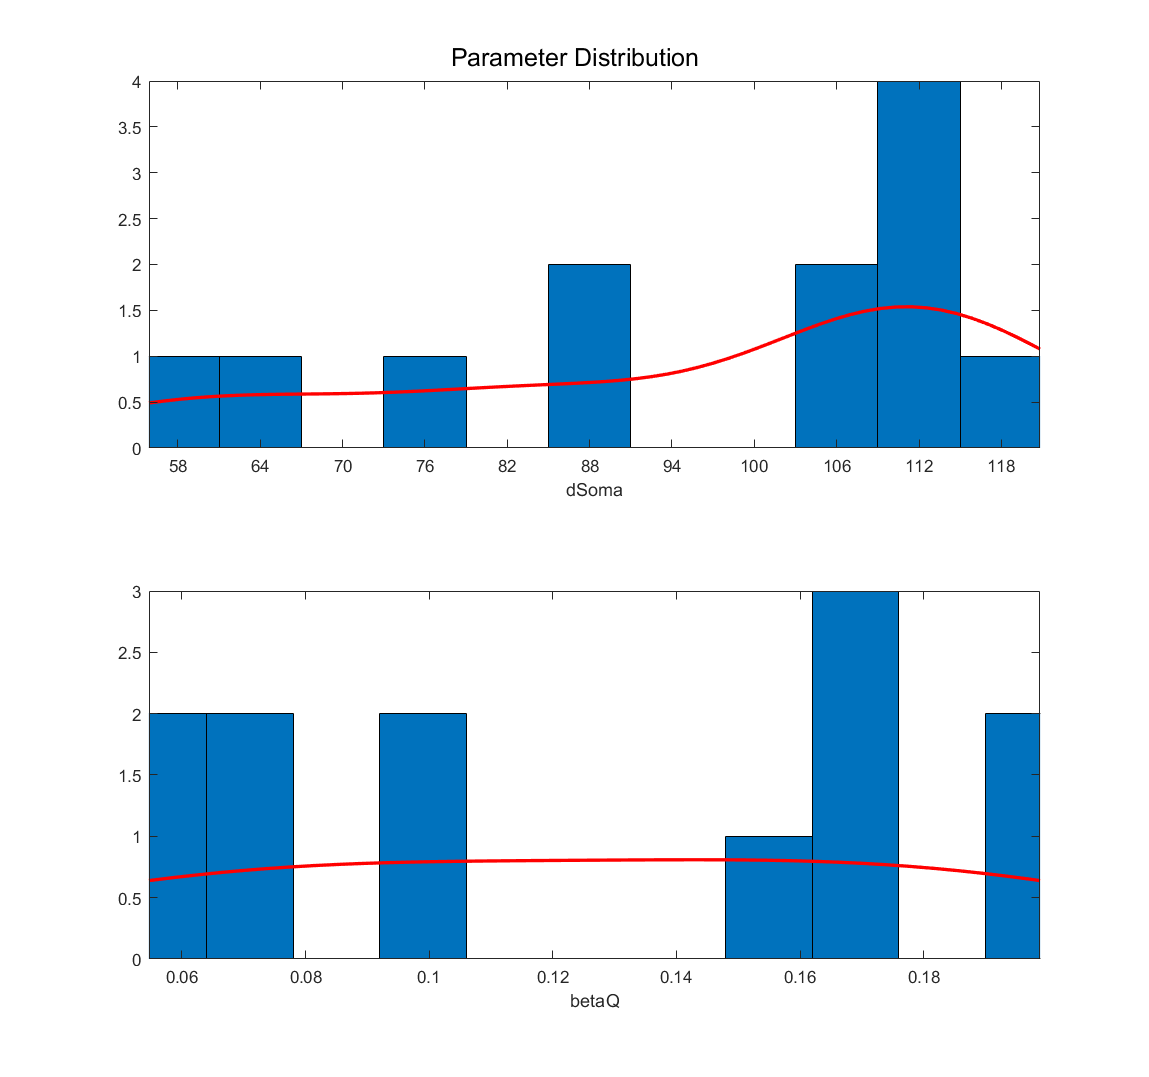

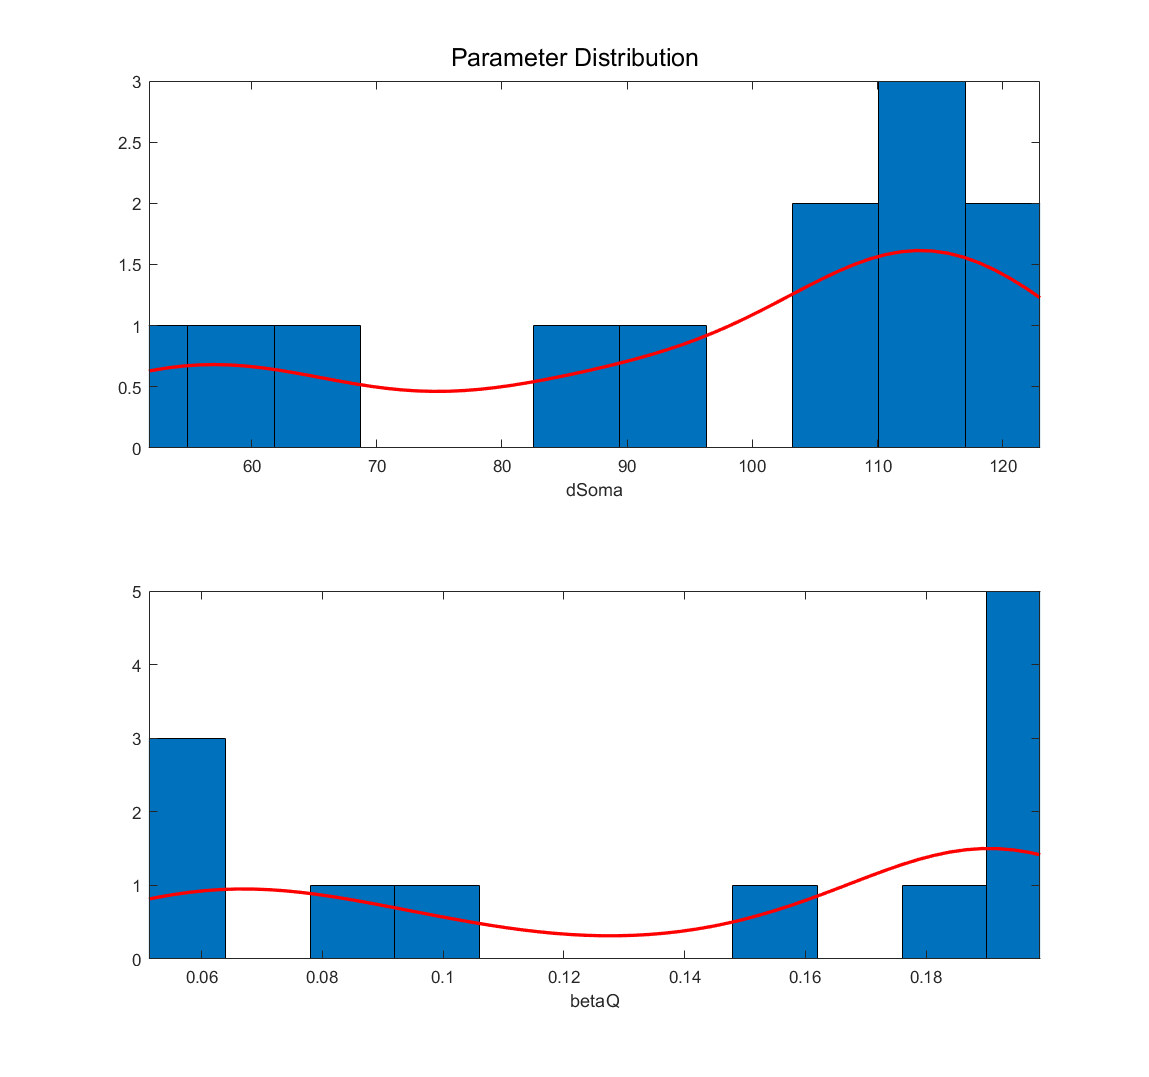

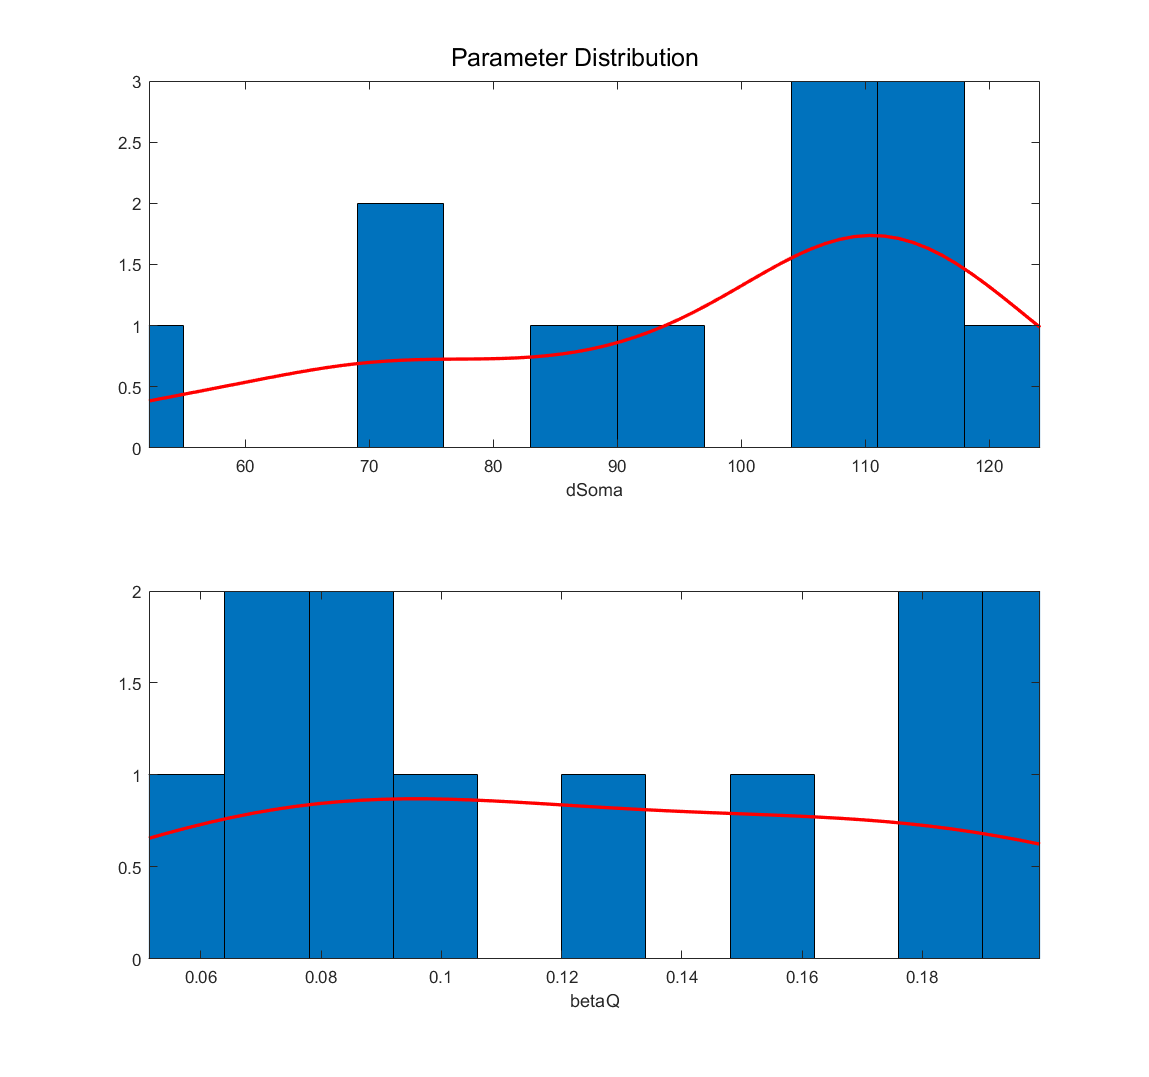

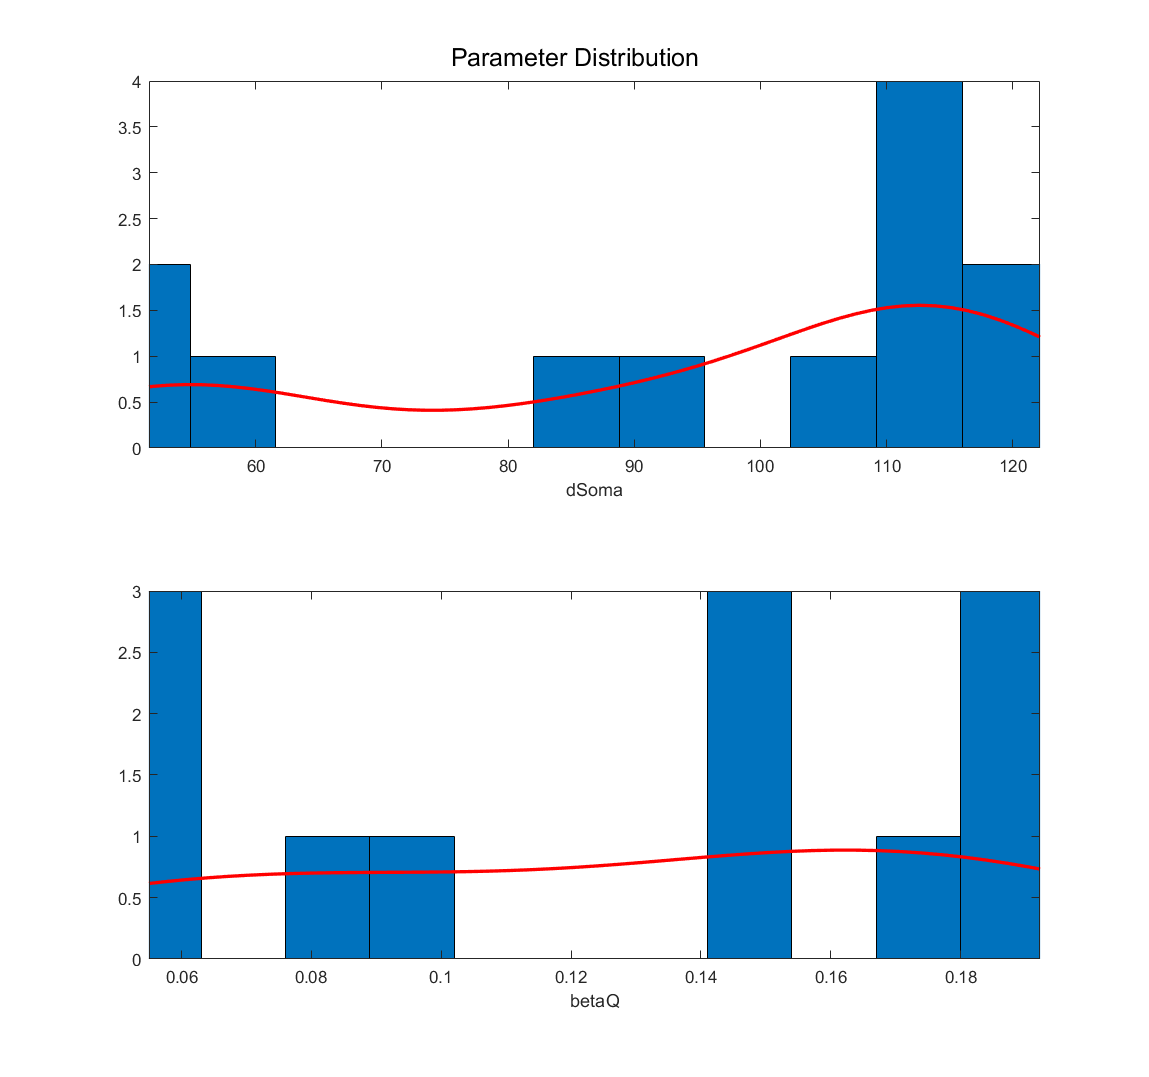

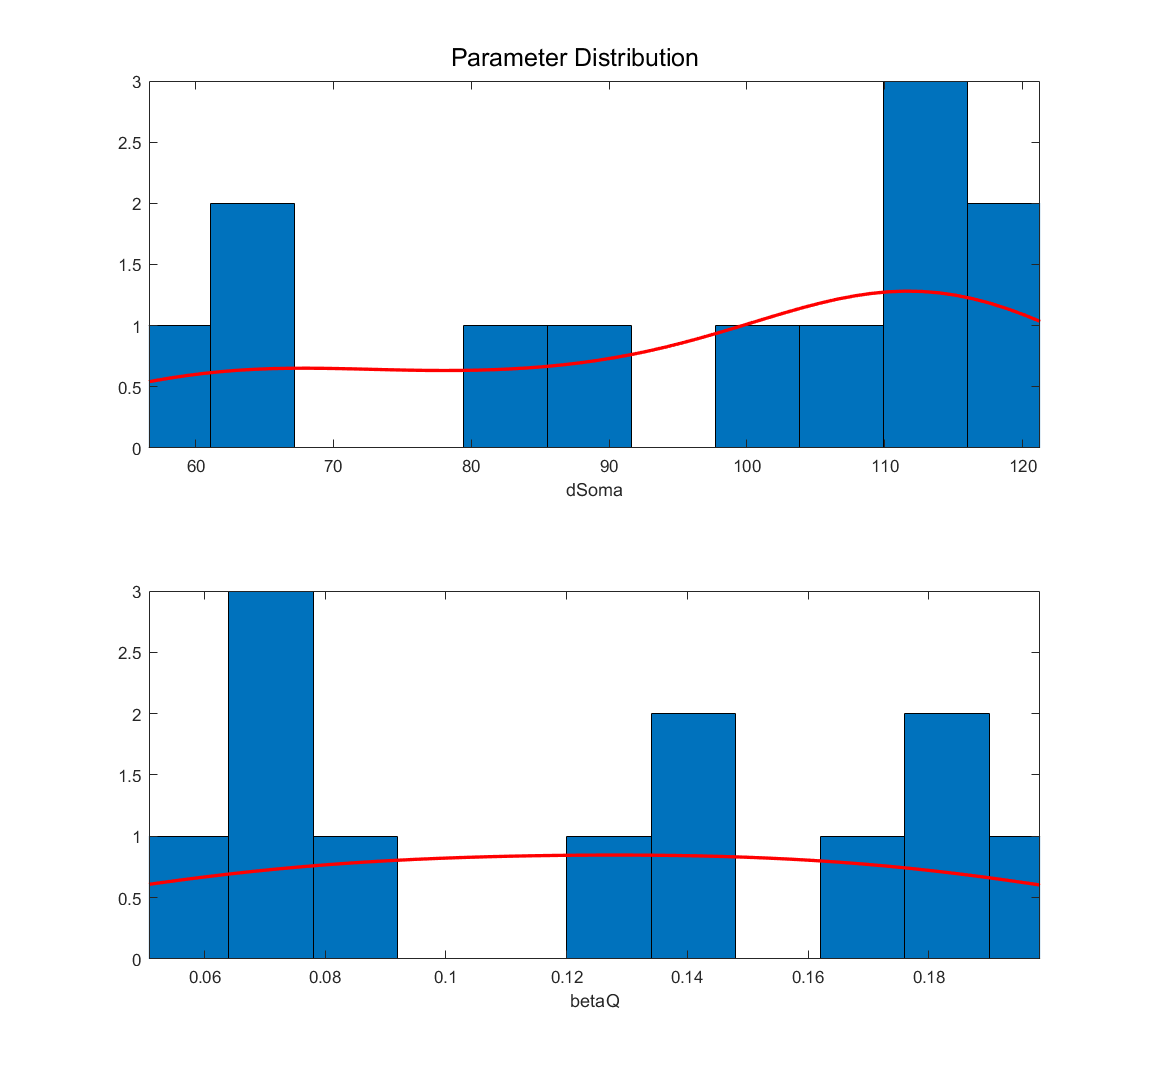

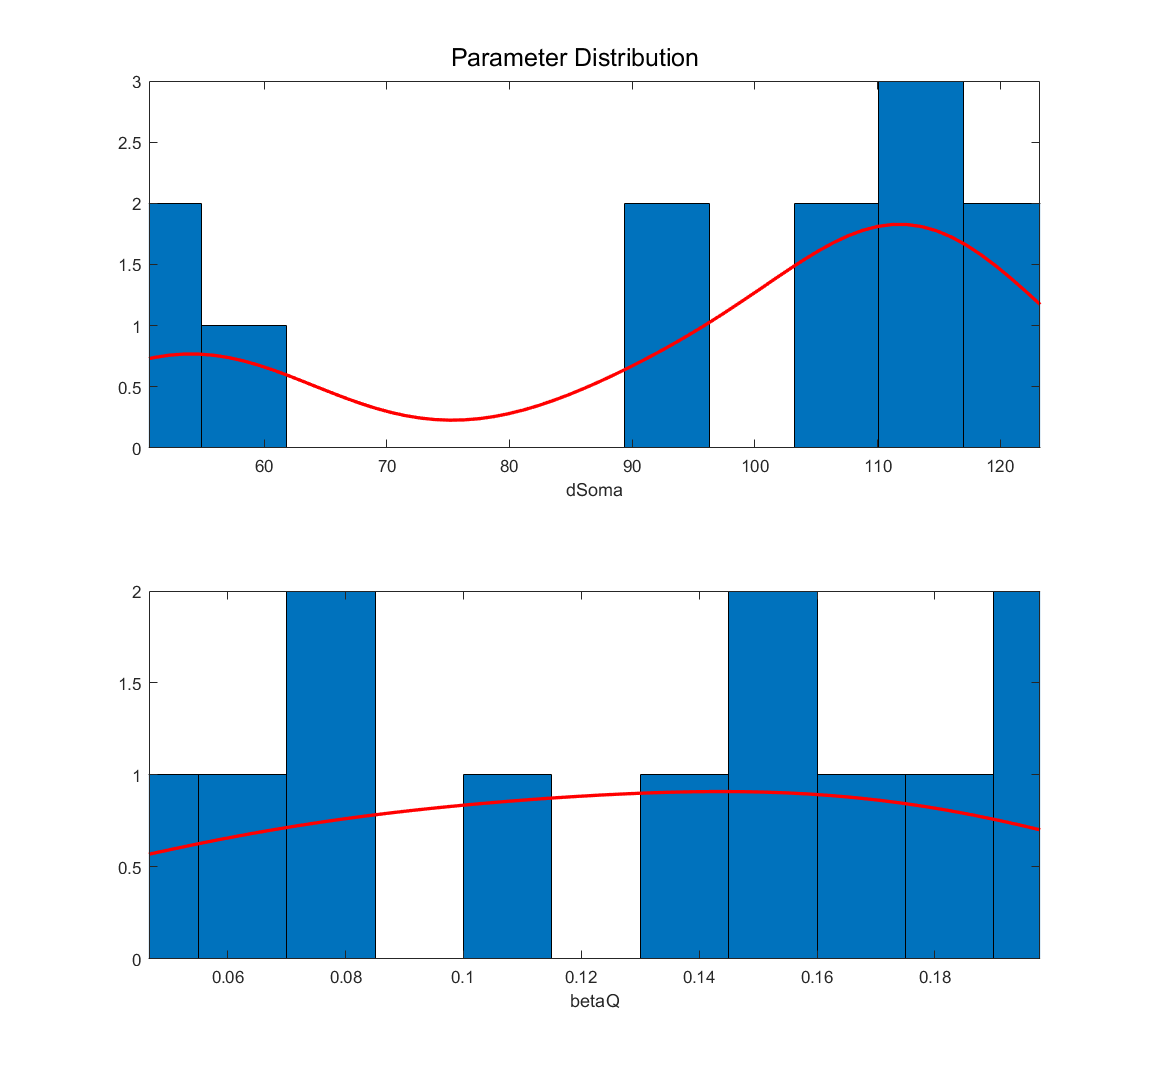

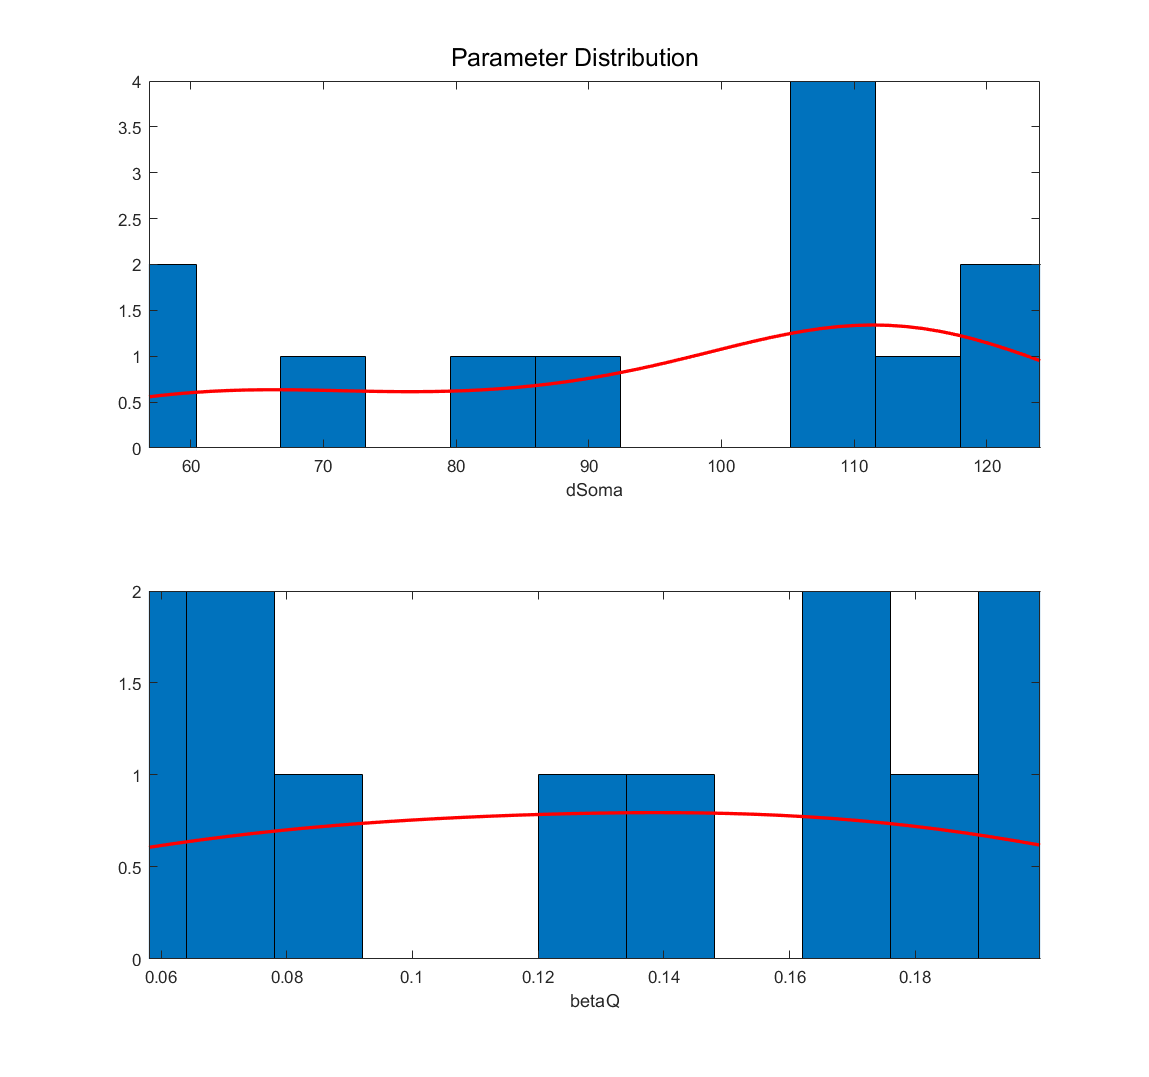

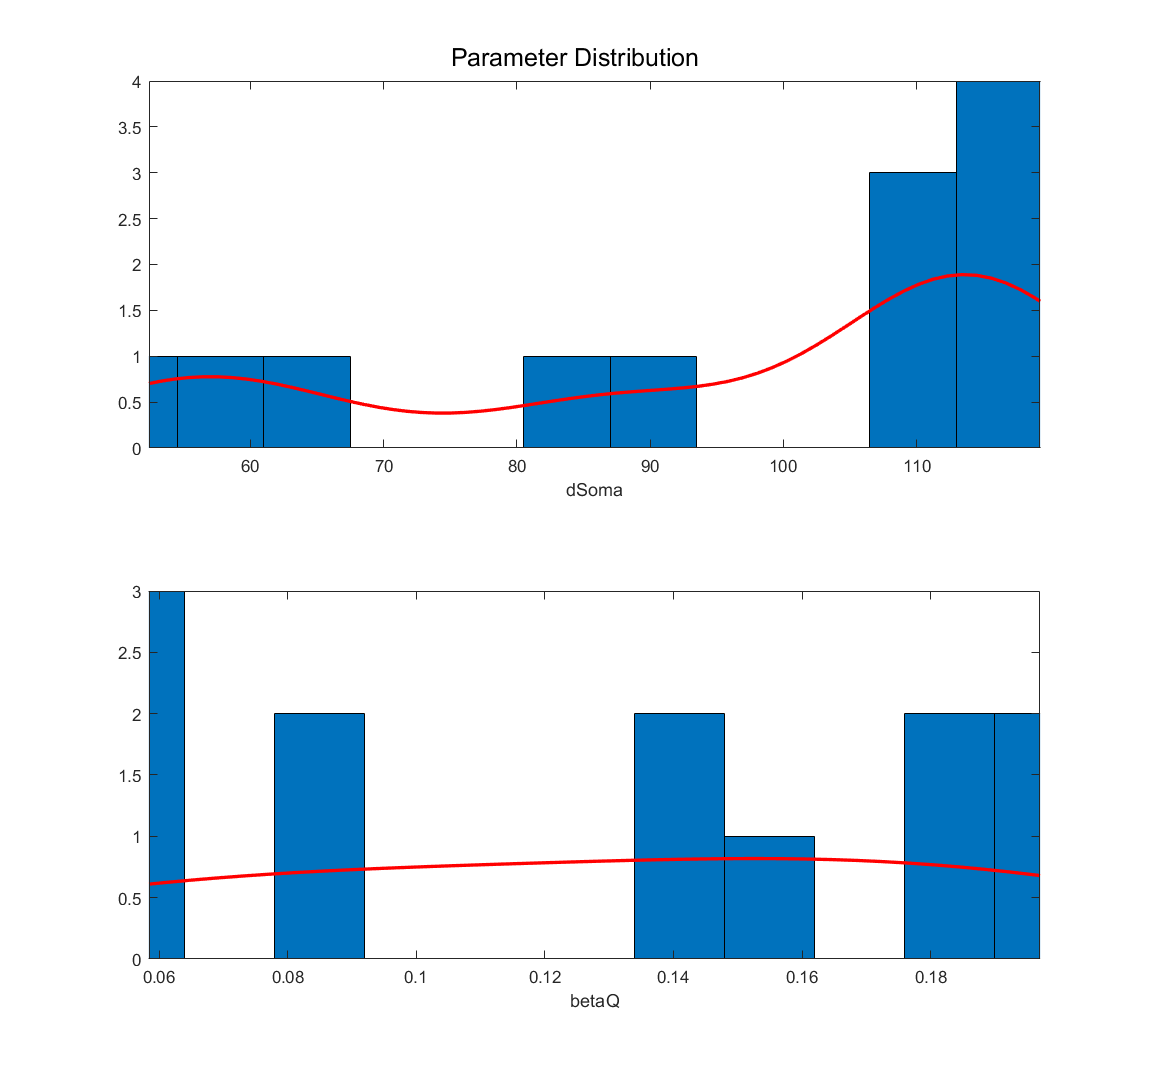

CurveData = cell(trials,length(data(1).Neuron(1).paramsLabel));
for i = 1:trials
    % Load data
    paramsLabel = data(i).Neuron(1).paramsLabel;
    lb = data(i).Neuron(1).lb;
    ub = data(i).Neuron(1).ub;
    tVec = data(i).Neuron(1).tVec;
    current = data(i).Neuron(1).current;
    % Reconstructing spikeTrainsExp
    n_neurons(i) = length(data(i).Neuron);
    spikeTrainsExp = zeros(length(data(i).Neuron(1).spikesExp_vec),n_neurons(i));
    for MNIndex = 1:n_neurons(i)
        spikeTrainsExp(:,MNIndex) = data(i).Neuron(MNIndex).spikesExp_vec;
    end
    % MakeFinalPlots(paramsLabel,lb,ub,current,spikesExp,parametersFinal,tVec,tspan)
    neuronpool_plot(i) = NeuronOptimization.MakeFinalPlots(paramsLabel,lb,ub,current,spikeTrainsExp,tVec,...
        data(i).parametersFinal);
    % plot the parameter distribution
    h = neuronpool_plot(i).plot_histogram();
    for ii = 1:length(h)
        CurveDataX{i,ii} = get(h{ii}(2),'xdata');
        CurveDataY{i,ii} = get(h{ii}(2),'ydata');
    end
end

## Compare the curves

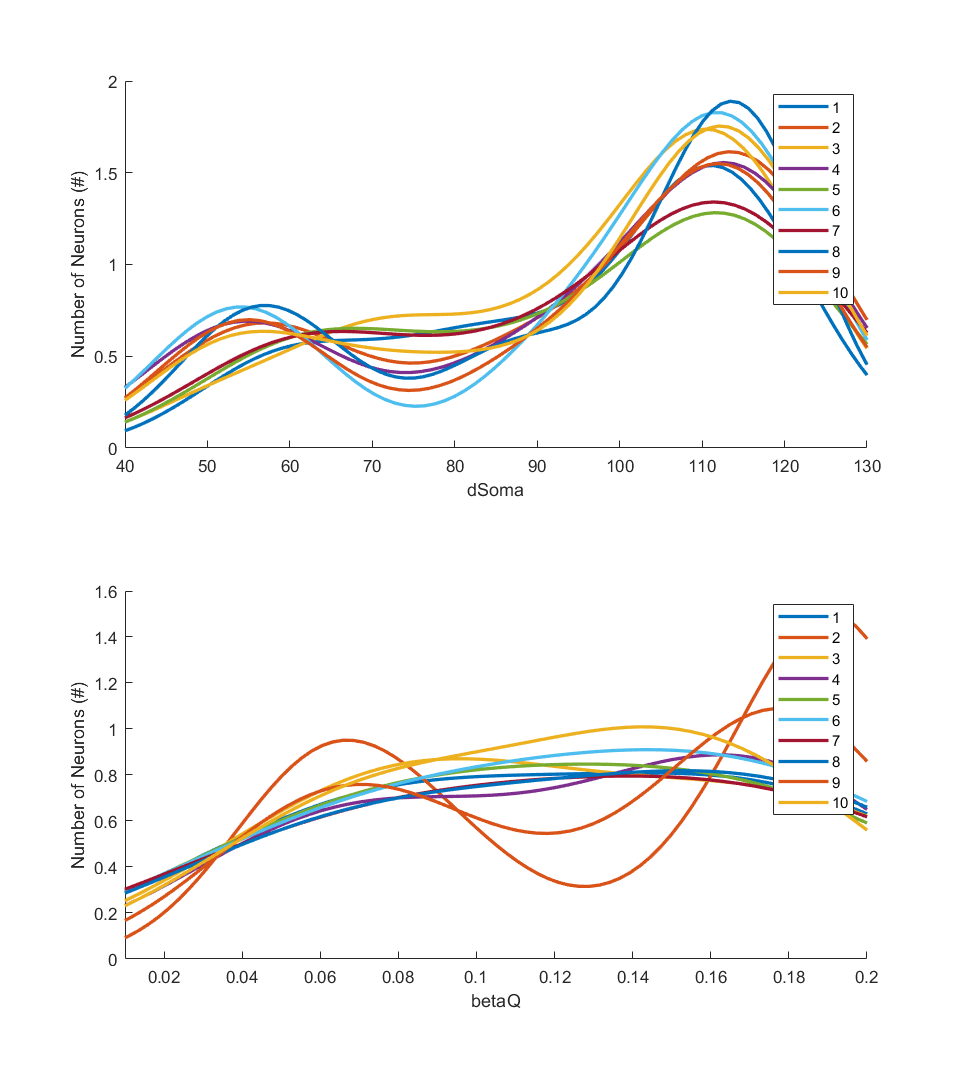

figure, clf
for ii = 1:length(paramsLabel)
    subplot(length(paramsLabel),1,ii), hold on
    for i = 1:trials
        plot(CurveDataX{i,ii},CurveDataY{i,ii},'LineWidth',2)
    end
    legend(trial)
    xlim([lb(ii),ub(ii)])
    xlabel(paramsLabel{ii})
    ylabel('Number of Neurons (#)')
end
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 0.5, 1]);

## PLOT ONE PARAMETER AGIST THE OTHER

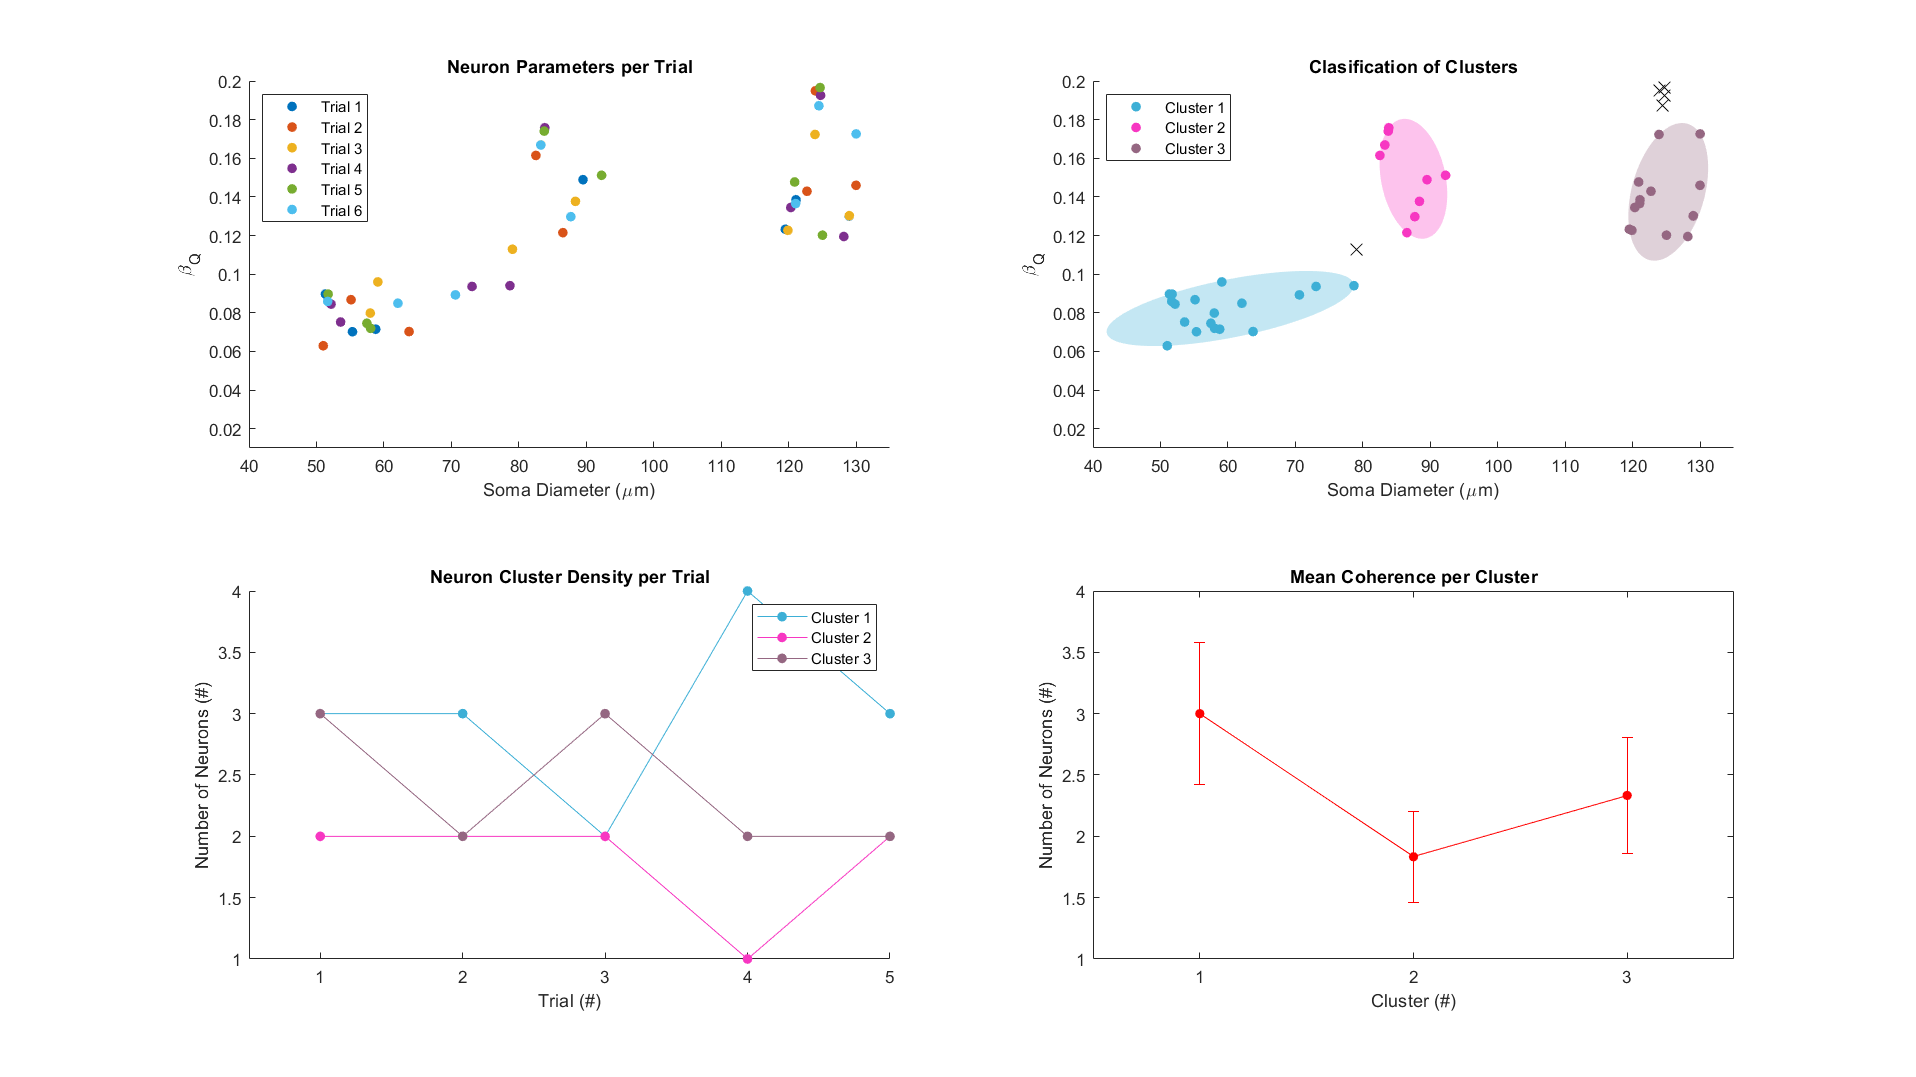

X_dSoma = NaN(max(n_neurons),trials);
X_betaQ = NaN(max(n_neurons),trials);
figure, clf
% Plot 1
subplot(2,2,1), hold on
for i = 1:trials
    plot(data(i).parametersFinal(:,1),data(i).parametersFinal(:,2),'.','MarkerSize',20)
    X_dSoma(1:length(data(i).parametersFinal(:,1)),i) = data(i).parametersFinal(:,1);
    X_betaQ(1:length(data(i).parametersFinal(:,2)),i) = data(i).parametersFinal(:,2);
    lg_names3{i} = ['Trial ' num2str(i)];
end
legend(lg_names3,'Location','northwest')
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q}')
xlim([40,135])
ylim([0.01,0.2])
title('Neuron Parameters per Trial')

X1 = reshape(X_dSoma,[],1); X2 = reshape(X_betaQ,[],1);
X1 = X1(~isnan(X1)); X2 = X2(~isnan(X2));
X = [X1,X2];
X_nor = normalize(X,'range');

% Plot 2
subplot(2,2,2), hold on
clusters = 3;
start = [0.1,0.4;
    0.8,0.8;
    0.9,0.1];
[idx,Centroids] = kmeans(X_nor,clusters,'Distance','cityblock','Start',start);
Distances = sqrt(sum((X_nor - Centroids(idx,:)).^2,2));
InC = Distances <= 3*std(Distances);
Ashby = cell(clusters,2);
for clus = 1:clusters
    color(clus,[1 2 3]) = rand(1,3);
    h_clus(clus) = plot(X(idx==clus & InC==1,1),X(idx==clus & InC==1,2),'.','MarkerSize',20,'Color',color(clus,:));
    lg_names{clus} = ['Cluster ' num2str(clus)];
    [A,c] = MinVolEllipse([X(idx==clus & InC==1,1)';X(idx==clus & InC==1,2)'],0.001);
    [U,Q,V] = svd(A);
    [x,y] = Functions.Ellipse(c,Q,V(2,2));
    fill(x,y,color(clus,:),'LineStyle','none','FaceAlpha',0.3)
    Ashby{clus,1} = x;
    Ashby{clus,2} = y;
end
plot(X(~InC,1),X(~InC,2),'x','MarkerSize',10,'Color',[15 15 15]/255);
% plot(Centroids(:,1),Centroids(:,2),'kx','MarkerSize',15,'LineWidth',3)
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q}')
legend(h_clus,lg_names,'Location','northwest')
xlim([40,135])
ylim([0.01,0.2])
title('Clasification of Clusters')

forStart = 1;
forEnd = 0;
for i = 1:trials
    forEnd = forEnd + n_neurons(i);
    DensityClus(i,[1,2,3]) = [sum(idx(forStart:forEnd)==1 & InC(forStart:forEnd)==1),...
        sum(idx(forStart:forEnd)==2 & InC(forStart:forEnd)==1),sum(idx(forStart:forEnd)==3 & InC(forStart:forEnd)==1)];
    forStart = forStart + n_neurons(i);
end

% Plot 3
subplot(2,2,3), hold on
for clus = 1:clusters
    plot(DensityClus(:,clus),'.-','MarkerSize',20,'Color',color(clus,:))
end
xticks(0:trials)
xlim([0.5,5])
xlabel('Trial (#)')
ylabel('Number of Neurons (#)')
legend(lg_names,'Location','northeast')
title('Neuron Cluster Density per Trial')

% Plot 4
subplot(2,2,4)
errorbar(mean(DensityClus,1),std(DensityClus,1),'-ro','MarkerSize',5,'MarkerEdgeColor','red','MarkerFaceColor','red')
xticks(0:clusters)
xlim([0.5,3.5])
xlabel('Cluster (#)')
ylabel('Number of Neurons (#)')
% legend(lg_names,'Location','eastoutside')
title('Mean Coherence per Cluster')

set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);

## SAVE ASHBY

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Ashby';
name = [MVC '_MVC'];
save([path '\' name '.mat'],'Ashby','X','n_neurons','DensityClus')
clear path, clear name

## COLOR MAP

% figure, clf, hold on
% hist3(X,'Nbins',[15 15])
% xlabel('Longitude')
% ylabel('Latitude')
% hold on
% N = hist3(X,'Nbins',[15 15]);
% N_pcolor = N';
% N_pcolor(size(N_pcolor,1)+1,size(N_pcolor,2)+1) = 0;
% xl = linspace(min(x),max(x),size(N_pcolor,2)); % Columns of N_pcolor
% yl = linspace(min(y),max(y),size(N_pcolor,1)); % Rows of N_pcolor
%
% h = pcolor(xl,yl,N_pcolor);
% colormap('hot') % Change color scheme
% colorbar % Display colorbar
% h.ZData = -max(N_pcolor(:))*ones(size(N_pcolor));
% ax = gca;
% ax.ZTick(ax.ZTick < 0) = [];
% title('Seamount Location Histogram and Intensity Map');
% view(45,45)

## GODLIKE REPEATABILITY

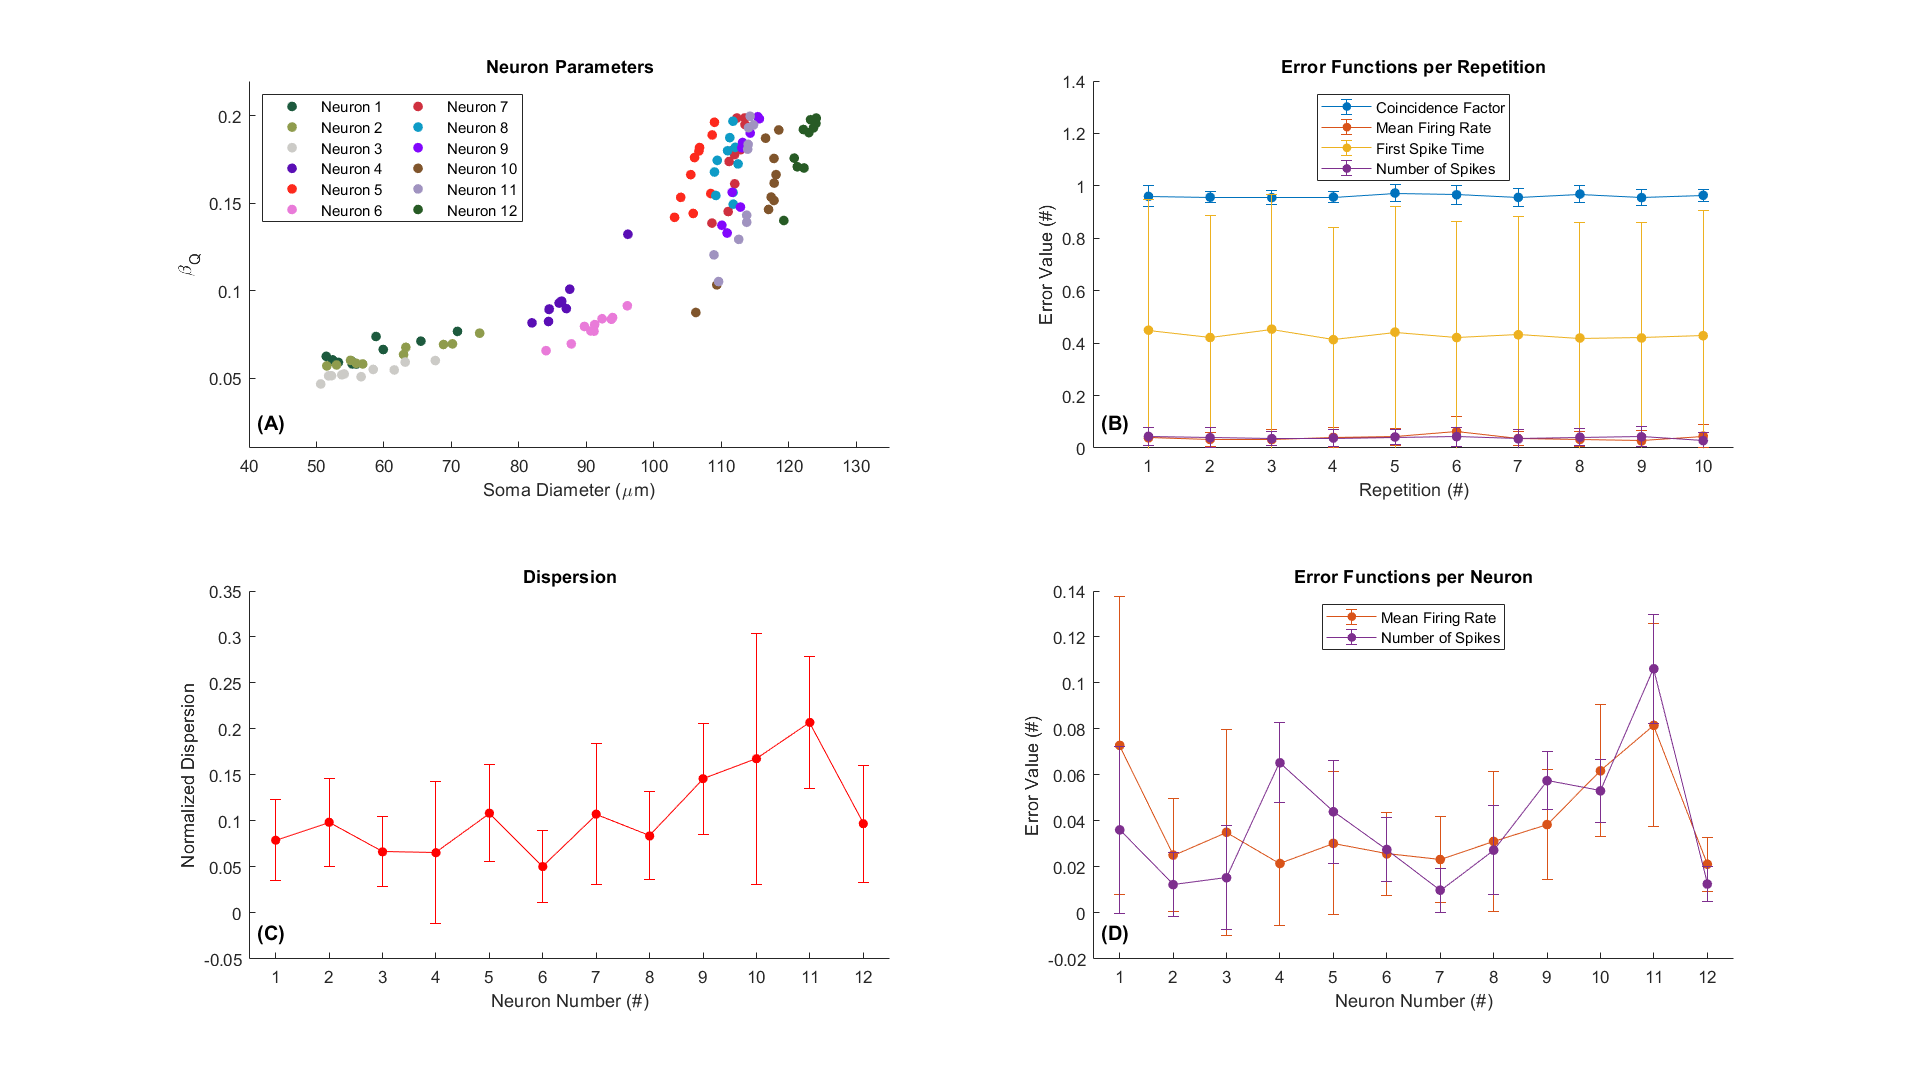

X_dSoma = NaN(max(n_neurons),trials);
X_betaQ = NaN(max(n_neurons),trials);
for i = 1:trials
    X_dSoma(1:length(data(i).parametersFinal(:,1)),i) = data(i).parametersFinal(:,1);
    X_betaQ(1:length(data(i).parametersFinal(:,2)),i) = data(i).parametersFinal(:,2);
end
X1 = reshape(X_dSoma,[],1); X2 = reshape(X_betaQ,[],1);
X1 = X1(~isnan(X1)); X2 = X2(~isnan(X2));
X = [X1,X2];
X_nor = normalize(X,'range');
collor = {'#0072BD','#D95319','#EDB120','#7E2F8E'};

figure, clf
% Plot 1
subplot(2,2,1), hold on
for i = 1:max(n_neurons)
    color(i,[1 2 3]) = rand(1,3);
    plot(X_dSoma(i,:),X_betaQ(i,:),'.','MarkerSize',20,'Color',color(i,:))
    lg_names3{i} = ['Neuron ' num2str(i)];
end
legend(lg_names3,'Location','northwest','NumColumns',2)
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q}')
xlim([40,135])
ylim([0.01,0.22])
title('Neuron Parameters')

% Plot 2
subplot(2,2,2), hold on
for i = 1:trials
    for ii = 1:length(data(i).Neuron)
        for j = 1:4
            errors_neurons(j,ii) = data(i).Neuron(ii).bestFactor(j);
        end
    end
    for j = 1:4
        errors_trial_mean(j,i) = mean(errors_neurons(j,:));
        errors_trial_std(j,i) = std(errors_neurons(j,:));
    end
end
for j = 1:4
    errorbar(errors_trial_mean(j,:),errors_trial_std(j,:),'.-','MarkerSize',20,'Color',collor{j})
end
xticks(0:trials)
xlim([0.1,trials+0.5])
xlabel('Repetition (#)')
ylabel('Error Value (#)')
ylim([0,1.4])
legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'},'Location','north')
title('Error Functions per Repetition')

% Plot 3
subplot(2,2,3), hold on
for i = 1:n_neurons(1)
    nn = 0:trials-1;
    range = nn.*n_neurons(1)+i;
    meanx(i) = mean(X_nor(range,1));
    meany(i) = mean(X_nor(range,2));
    Dispersion(:,i) = sqrt(sum((X_nor(range,:) - [meanx(i) meany(i)]).^2,2));
end
errorbar(mean(Dispersion,1),std(Dispersion,1),'-ro','MarkerSize',5,'MarkerEdgeColor','red','MarkerFaceColor','red')
xticks(0:n_neurons(1))
xlim([0.5,n_neurons(1)+0.5])
xlabel('Neuron Number (#)')
ylabel('Normalized Dispersion')
title('Dispersion')

% Plot 4
subplot(2,2,4), hold on
for i = 1:trials
    for ii = 1:length(data(i).Neuron)
        for j = 1:4
            errors_neurons2{j}(i,ii) = data(i).Neuron(ii).bestFactor(j);
        end
    end
    for j = 1:4
        errors_trial_mean2{j} = mean(errors_neurons2{j});
        errors_trial_std2{j} = std(errors_neurons2{j});
    end
end
for j = 2:2:4
    errorbar(errors_trial_mean2{j},errors_trial_std2{j},'.-','MarkerSize',20,'Color',collor{j})
end
xticks(0:n_neurons(1))
xlim([0.5,n_neurons(1)+0.5])
xlabel('Neuron Number (#)')
ylabel('Error Value (#)')
% ylim([0,1.4])
% legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'},'Location','north')
legend({'Mean Firing Rate','Number of Spikes'},'Location','north')
title('Error Functions per Neuron')

set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);
AddLetters2Plots(gcf, 'HShift', 0, 'VShift', 0.3, 'Direction', 'LeftRight')

% Plot 3
% subplot(1,2,2), hold on
% for i = 1:n_neurons(1)
%     nn = 0:9;
%     range = nn.*12+i;
%     meanx(i) = mean(X(range,1));
%     meany(i) = mean(X(range,2));
%     stdx(i) = std(X(range,1));
%     stdy(i) = std(X(range,2));
% end
% CoVx = meanx./stdx; CoVy = meany./stdy;
% Dispersion = CoVx + CoVy;
% plot(Dispersion,'.-','MarkerSize',20)
% xticks(0:n_neurons(1))
% xlim([0.5,12.5])
% xlabel('Neuron Number (#)')
% ylabel('CoV')
% title('Mean Coherence of Dispersion')
% Cov_values = data2.Trial(2).COV_ISI_vec(data2(1).Trial(2).QCids.Selected);
% [Cov_values,I] = sort(Cov_values);
% for i = 1:12
%     spikeTimesExp = find(data(1).Neuron(i).spikesExp_vec == 1);
%     meanFiringRateExp(i) = mean(1./diff(spikeTimesExp/2048));
%     firstSipkeTime(i) = spikeTimesExp(1)/2048;
% end
% firstSipkeTime = normalize(firstSipkeTime,'range');
% meanFiringRateExp = normalize(meanFiringRateExp,'range');
% % yyaxis left
% [meanFiringRateExp,I] = sort(meanFiringRateExp+firstSipkeTime);
% meanDispersion = mean(Dispersion,1);
% plot(meanFiringRateExp,meanDispersion(I),'.-','MarkerSize',20)
% % plot(meanFiringRateExp+firstSipkeTime,'.-','MarkerSize',20)
% % yyaxis right
% % plot(firstSipkeTime,'.-','MarkerSize',20)